# Homework #2

Math 3607

Ian McCamey

## Problem 1. 

y1 = 2020;
isLeapYear(y1)

ans = logical
   1


y2 = 1900;
isLeapYear(y2)

ans = logical
   0


y3 = 2000;
isLeapYear(y3)

ans = logical
   1


leapYears = [];
for i = 1900:2023
    if isLeapYear(i)
        leapYears = [leapYears, [i]];
    end
end
disp(reshape(leapYears, 6, 5)')

        1904        1908        1912        1916        1920        1924
        1928        1932        1936        1940        1944        1948
        1952        1956        1960        1964        1968        1972
        1976        1980        1984        1988        1992        1996
        2000        2004        2008        2012        2016        2020



## Problem 2. 

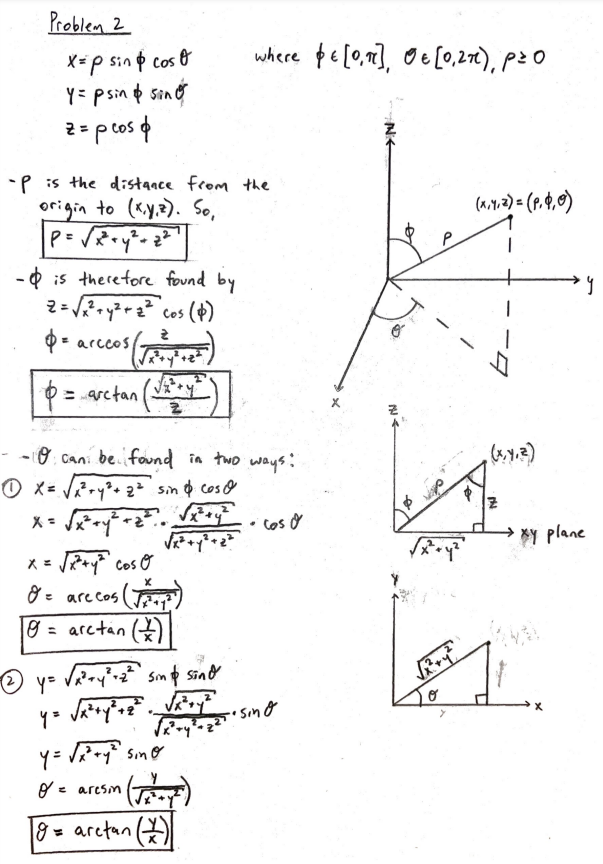

[rho, phi, theta] = toSpherical(1, 2, -2) 

rho = 3

phi = 2.3005

theta = 1.1071

[rho, phi, theta] = toSpherical(0, -3, 4)

rho = 5

phi = 0.6435

theta = 4.7124

[rho, phi, theta] = toSpherical(-5, -12, 1)

rho = 13.0384

phi = 1.4940

theta = 1.1760

[rho, phi, theta] = toSpherical(0, 0, -7)

rho = 7

phi = 0

theta = 0

## Problem 3. 

format shortE
points = [-30 -3 3 30];
myexp(points)

ans =    9.3576e-14   4.9787e-02   2.0086e+01   1.0686e+13


## Problem 4. 

format default
wins = 0;
trials = 0;

while(trials < 1000000)
    trials = trials + 1;
    stick1 = rand();
    stick2 = rand();
    stick3 = rand();

    if(stick1 < stick2 + stick3 && stick2 < stick1 + stick3 && stick3 < stick1 + stick2)
        wins = wins + 1;
    end
end

winprob = wins/trials;
fprintf('Estimated win probability: %.2f%%', winprob * 100)

Estimated win probability: 49.97%

## Problem 5. 

p_heads = 1/3;
p_tails = 2/3;

for i = 1:10
    countHeads = 0;
    countTails = 0;
    while (abs(countTails - countHeads) < 10)
        toss = rand();
        if(toss < 2/3)
            countTails = countTails + 1;
        else
            countHeads = countHeads + 1;
        end
    end
    trials = countHeads + countTails;
    fprintf('Simulation %2.15g done in %2.15g tosses.\n', i, trials)
end

Simulation  1 done in 32 tosses.
Simulation  2 done in 36 tosses.
Simulation  3 done in 50 tosses.
Simulation  4 done in 14 tosses.
Simulation  5 done in 30 tosses.
Simulation  6 done in 20 tosses.
Simulation  7 done in 24 tosses.
Simulation  8 done in 22 tosses.
Simulation  9 done in 34 tosses.
Simulation 10 done in 14 tosses.


## Problem 6. 

n = 0;
a_n = 0;
while abs(a_n - pi) > 10^-6
    a_n = 0;
    for k = 0:n
        a_n = a_n + (6/sqrt(3))*((-1)^k)/(3^k*(2*k+1));
    end
    fprintf('a_%d = %4.4f\n', n, a_n)
    n = n + 1;
end

a_0 = 3.4641
a_1 = 3.0792
a_2 = 3.1562
a_3 = 3.1379
a_4 = 3.1426
a_5 = 3.1413
a_6 = 3.1417
a_7 = 3.1416
a_8 = 3.1416
a_9 = 3.1416
a_10 = 3.1416


n = 0;
b_n = 0;
while abs(b_n - pi) > 10^-6
    b_n = 0;
    for k = 0:n
        b_n = b_n + 16*((-1)^k)/(5^(2*k+1)*(2*k+1)) - 4*((-1)^k)/(239^(2*k+1)*(2*k+1));
    end
    fprintf('b_%d = %4.4f\n', n, b_n)
    n = n + 1;
end

b_0 = 3.1833
b_1 = 3.1406
b_2 = 3.1416
b_3 = 3.1416


## Functions Used

function [result] = isLeapYear(year)
    if mod(year, 100) == 0 && mod(year, 400) == 0
        result = true;
    elseif mod(year, 100) ~= 0 && mod(year, 4) == 0
        result = true;
    else
        result = false;
    end
end

**NOTE:** $\arctan(x): \mathbb{R} \rightarrow \left(-\frac{\pi}{2}, \frac{\pi}{2}\right)$, $\phi \in [0, \pi]$, $\theta \in [0, 2\pi)$.

function[rho, phi, theta] = toSpherical(x, y, z)
    rho = sqrt(x^2 + y^2 + z^2);
    phi = atan(sqrt(x^2+y^2)/z);
    theta = atan(y/x);

    if phi < 0
        phi = phi + pi;
    end
    if theta < 0
        theta = theta + 2*pi;
    end
    if x == 0 && y == 0
        theta = 0;
    end
end

function[results] = myexp(points)
    polynomial = zeros(1, 16);
    results = zeros(1, length(points));
    dividedBy2 = zeros(1, length(points));

    % calculating 16 Taylor Series coefficients
    for i = 1:16
        polynomial(i) = 1/factorial(i-1);
    end
    
    % dividing each input by 2 until absolute value < 0.5
    for j = 1:length(points)
        while abs(points(j)) >= 0.5
            points(j) = points(j) / 2;
            dividedBy2(j) = dividedBy2(j) + 1;
        end
    end
    
    % evaluating Taylor Series at each input, squaring repeatedly
    polynomial = flip(polynomial);
    for k = 1:length(results)
        results(k) = polyval(polynomial, points(k));
        for x = 1:dividedBy2(k)
            results(k) = results(k)^2;
        end
    end
end